#   ECSE 343: Numerical Methods in Engineering

#  Assignment 4

Due Date: 31st March 2025

Student Name: Deniz Karakus

Student ID: 261114510

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

**Question 1: 5marks **

**a) **For two given matrices $A,B\in \Re^{\;N\times N} \;\ldotp$ Is $e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B} ?\;$Explain.

**No. The exponential of a matrix is defined by its power series: e^X = I + X + X^2/2! + X^3/3! + .... When we compute e^(A+B), we get I + (A+B) + (A+B)^2/2! + (A+B)^3/3! + ... After expanding using the binomial theorem, we end up with terms where A and B are multiplied in various orders. However, when we do e^A * e^B, we end up with terms where A is always to the left of B. We know that these won't be equal expressions for all matrices, so no, e^A * e^B is not always equal to e^(A+B).**

**b)  **Under what condition is $e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B} \;$? Elaborate.

$e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B} \;$** when A and B commute, meaning AB = BA. Like I mentioned in the previous answer, when we expand e^(A+B), we get terms where A and B are sometimes on the right and on the left of each other. However, if AB = BA, then it won't matter the way in which they're multiplied, so **$e^{\mathit{\mathbf{A}}} \ldotp e^{\mathit{\mathbf{B}}} =e^{\mathit{\mathbf{A}}+B}$** when A and B commute. **

**Question 2:  Eigenvalues (15 marks)**

a) The Power Iteration method is used to compute the dominant eigen value  and the  eigen vector associated with the  dominant eigen value of a given matrix. Any random vector $x_0$ can be written as the linear combination of $n$ independent eigen vectors of a matrix ${\mathit{\mathbf{A}}}_{n\times n}$ as 


$${\mathit{\mathbf{x}}}_{0\;} =c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\mathit{\mathbf{v}}}_2 +\cdots +c_n {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;} \;\;\;$$
                                             
$$\left(1\right)$$


On multiplying the above with matrix $\mathit{\mathbf{A}}$ we get,


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\mathit{\mathbf{A}}\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;}$$
                                  
$$\left(2\right)$$


The vectors ${\mathit{\mathbf{v}}}_i$'s are the eigen vectors of matrix $\mathit{\mathbf{A}}$, therefore, $\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}} =\lambda_{i\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$. The symbol  $\lambda_{i\;}$denotes the eigen value corresponding to eigen vector ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$.  


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;} \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                                
$$\left(3\right)$$


Equation (3), can be  generalised to 


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;}^{k\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;}^k \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;}^{k\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                              
$$\left(4\right)$$


Without loss of generality (4) can be written as


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =\lambda_{1\;}^{k\;} \left(c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\frac{\lambda_{2\;}^k }{\lambda_{1\;}^{k\;} }\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \frac{\lambda_{n\;}^{k\;} }{\lambda_{1\;}^{k\;} }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;} \right)$$
                     
$$\left(5\right)$$


Assuming that $\left|\lambda {\;}_1 \right|>$$\left|\lambda_2 \right|>\cdots \left|\lambda_n \right|$.  As $k\to \infty$, the terms with  $\frac{\lambda_{j\;}^k }{\lambda_{1\;}^{k\;} }\to 0$.  Thus, as $k\to \infty$,  ${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;}$converges to the eigen vector ${\mathit{\mathbf{v}}}_{1\;}$ corresponding to the largest eigen value. Write an iterative algorithm which computes the eigen vector and eigen value using the following recurssive formula,


$${\mathit{\mathbf{v}}}^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel }$$
                                                                   
$$\left(6\right)$$
   

where ${\mathit{\mathbf{v}}}^{\left(k+1\right)}$ is the eigen vector at ${\left(k+1\right)}^{\textrm{th}}$iteration.

 Stop the algorithm using when the $\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel \;<\epsilon_{\textrm{tol}}$, where $\epsilon_{\textrm{tol}}$ is the input tolerance value. 

Write a MATLAB function power_method(A,tol) that uses power iteration algorithm to compute the dominant eigen value and the eigenvector. 

Use the cell below to test the your fucntion, you can use MATLAB's built in function, eig (see MATLAB documentation) to compare your answers.

M = randi(15,5)/10;
A = M'*M;
[e,v]= power_method(A,1e-4)

e = 27.4875

v =     0.4271
    0.4345
    0.4672
    0.4658
    0.4399


[V_matlab, D_matlab] = eig(A);
[e_matlab, idx] = max(abs(diag(D_matlab)));
e_matlab = D_matlab(idx, idx)

e_matlab = 27.4875

v_matlab = V_matlab(:, idx)

v_matlab =     0.4271
    0.4345
    0.4672
    0.4658
    0.4399


b)  The eigen vectors of the **real and symmeteric **matrices are orthogonal to each other.  We can use this fact along with the power iteration method to compute all the eigen values and eigen vectors. The idea is to compute the first dominant eigne vector and then project out the previous eigen vectors using the Gram-Schmidt approch. Given that we computed the first $\left(l-1\right)$ eigen vectors, ${\mathit{\mathbf{v}}}_1 ,{\mathit{\mathbf{v}}}_{2\;} ,\cdots ,{\mathit{\mathbf{v}}}_{l-1}$, we can use the power iteration algorithm to compute the $l^{\textrm{th}\;}$eigen vector, ${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}$, as following,

*Step 1. Start with a arbitrary intial guess vector *${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(0\right)}$*.*

*Step 2. Project out the previous eigen vectors using the Gram-Schmidt,*

        
$${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} ={\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} -{\textrm{proj}}_{\textrm{span}\left\lbrace {\mathit{\mathbf{v}}}_1 ,{\mathit{\mathbf{v}}}_{2\;} ,\cdots ,{\mathit{\mathbf{v}}}_{l-1} \right\rbrace } {\mathit{\mathbf{v}}}_l^{\left(k\right)}$$



$${\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} ={\mathit{\mathbf{v}}}_{\mathit{\mathbf{l}}}^{\left(k\right)} -\sum_{j=1}^{l-1} \left({\mathit{\mathbf{v}}}_j^T {\;\mathit{\mathbf{v}}}_l^{\left(k\right)} \right){\mathit{\mathbf{v}}}_j^T$$


*Step 3. Carry out the power iteration using the recurssive formula, *${{\mathit{\mathbf{v}}}_l }^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_l^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_l^{\left(k\right)} \parallel }$

*Step 4. Check for convergence, if *$\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel >\epsilon_{\textrm{tol}}$* repeat steps 2 and 3.*

The above method is prone to numerical errors, therefore, the above algorithm is seldomly used.  Instead we use a more stable verison of this algorithm which performs the orthogonalisation process described in Step 2, sumultaneously on all the vectors.

In the **simulatanous orthogonalisation **method we start with ${\mathit{\mathbf{Q}}}_0$ matrix containing the initial guesses for all eigen vectors, 


$${\mathit{\mathbf{Q}}}_0 =\left\lbrack {\mathit{\mathbf{v}}}_1^{\left(0\right)} \;\;{\mathit{\mathbf{v}}}_2^{\left(0\right)} \;{\mathit{\mathbf{v}}}_3^{\left(0\right)} \cdots {\mathit{\mathbf{v}}}_n^{\left(0\right)} \right\rbrack$$


The most obivious choice for the intial guess matrix is an identity matrix of same size as matrix $\mathit{\mathbf{A}}\ldotp$ In the next step we carry out the power iteration on the Intial guess matrix.


$${\textrm{AQ}}_0 =\left\lbrack {\textrm{Av}}_1^{\left(0\right)} \;\mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_2^{\left(0\right)} \;\mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_3^{\left(0\right)} \cdots \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_n^{\left(0\right)} \right\rbrack$$


Since we know that eigen vectors of symmeteric and real matrices are othogonal to each other, so we orthogonalise and normalise the columns of the matrix ${\textrm{AQ}}_0$. The most obvious choice is to perform QR decompostion on matrix ${\textrm{AQ}}_0$ as shown below,

 
$${\textrm{AQ}}_0 ={\mathit{\mathbf{Q}}}_1 {\mathit{\mathbf{R}}}_1$$
 

The use of QR decompostion is the obivious choice because the columns of ${\mathit{\mathbf{Q}}}_1$ are orthonormal. Next we carry out the power iteration by multiplying the columns of the matrix ${\mathit{\mathbf{Q}}}_1$ with $\mathit{\mathbf{A}}\ldotp$ This process can be summerised as,

*Step 1. Start with initial guess for all eigen vectors using matrix, *${\mathit{\mathbf{Q}}}_0$*.*

*Step 2. Compute the power iteration *${\textrm{AQ}}_k$*.*

*Step 3. Get *${\mathit{\mathbf{Q}}}_{k+1}$*, the matrix containing orthogonalised and normalised the columnn of  *${\textrm{AQ}}_k$*. Use QR decomposition to obtain *${\mathit{\mathbf{Q}}}_{k+1}$*.*

*Step 4. Check for convergence, if *$\parallel {\mathit{\mathbf{Q}}}_{k+1} -{\mathit{\mathbf{Q}}}_k \parallel >\epsilon_{\textrm{tol}}$*, repeat steps 2 and 3.*

Write a MATLAB function *simultaneous_orthogonalisation(A,1e-4) *to compute the all eigen values and eigen vectors using  **simulataneous-orthogonalisation **, the function should take the matrix and tolerance as inputs.  Use the same matrix as part (a).

Use the cell below to test the your function. 

M = randi(15,5)/10;
A = M'*M;
[V1,eigen1] = simultaneous_orthogonalisation(A,1e-4)

V1 =    -0.2349   -0.1226    0.3092    0.9050   -0.1229
   -0.5568   -0.7551    0.0363   -0.2236    0.2617
   -0.4825    0.1191   -0.0745   -0.1979   -0.8416
   -0.5235    0.5876    0.4581   -0.1611    0.3806
   -0.3578    0.2352   -0.8293    0.2565    0.2515


eigen1 =    15.3577
    1.0407
    0.7302
    0.7118
    0.2796


[V_matlab, D_matlab] = eig(A);
eigenValues_matlab = diag(D_matlab);
[sorted_matlab_eigenvals, idx_matlab] = sort(abs(eigenValues_matlab), 'descend')

sorted_matlab_eigenvals =    15.3577
    1.0407
    0.7302
    0.7118
    0.2796


idx_matlab =      5
     4
     3
     2
     1


V_matlab_sorted = V_matlab(:, idx_matlab)

V_matlab_sorted =     0.2349    0.1226    0.3057    0.9062    0.1229
    0.5568    0.7551    0.0371   -0.2235   -0.2617
    0.4825   -0.1191   -0.0737   -0.1982    0.8416
    0.5235   -0.5876    0.4587   -0.1594   -0.3806
    0.3578   -0.2352   -0.8302    0.2533   -0.2515


c) The QR-algorithm is the standard algorithm for computing the eigen values. As you can guess, this involves the QR-factorization of the matrix in question. This algorithm proceeds by computing the QR transfrom of the given matrix $\mathit{\mathbf{A}}$ as 


$$\mathit{\mathbf{A}}\;\overset{\textrm{QR}\;\textrm{decom}\ldotp }{=} {\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{R}}}_1$$


Next, the we right multiply the above equation with ${\mathit{\mathbf{Q}}}_{1\;}$and left multiply with ${\mathit{\mathbf{Q}}}_{1\;}^T$.


$${\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} ={\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_{1\;}$$


Next we compute the QR decomposion of ${\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_{1\;}$, then the above eqauation can be written as 

                                                        
$${\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} ={\mathit{\mathbf{Q}}}_2 {\mathit{\mathbf{R}}}_{2\;}$$
       
$$\textrm{where}\;\;{\mathit{\mathbf{R}}}_1 {\mathit{\mathbf{Q}}}_1 \;\overset{\textrm{QR}\;\textrm{decom}\ldotp }{=} {\mathit{\mathbf{Q}}}_{2\;} {\mathit{\mathbf{R}}}_2$$


Again, the we right multiply the above equation with ${\mathit{\mathbf{Q}}}_{2\;}$and left multiply with ${\mathit{\mathbf{Q}}}_{2\;}^T$.


$${\mathit{\mathbf{Q}}}_2^{T\;} {\mathit{\mathbf{Q}}}_{1\;}^{T\;} \mathit{\mathbf{A}}\;{\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{Q}}}_2 ={\mathit{\mathbf{R}}}_{2\;} {\mathit{\mathbf{Q}}}_2$$


We can repeat the above procedure for $k$ iterations, and we get the following 


$${\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}\;}^{T\;} {\mathit{\mathbf{Q}}}_{k-1}^T \cdots {\mathit{\mathbf{Q}}}_2^{T\;} {\mathit{\mathbf{Q}}}_{1\;}^{T\;\;} \mathit{\mathbf{A}}\;\;{\mathit{\mathbf{Q}}}_{1\;} {\mathit{\mathbf{Q}}}_2 \ldotp \ldotp \ldotp {\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}-1} {\mathit{\mathbf{Q}}}_{\mathit{\mathbf{k}}} ={\mathit{\mathbf{R}}}_{k\;} {\mathit{\mathbf{Q}}}_k$$


It can be shown ${\mathit{\mathbf{R}}}_{k\;}$converges to a upper triangular matrix as  $k\longrightarrow \infty$ and diagonal of the matrix${\;\mathit{\mathbf{R}}}_{k\;} {\mathit{\mathbf{Q}}}_k$ converges to eigen values. 

 Write a MATLAB function,* QR_algorithm(A,1e-4)*, that implements the QR-algorithm to compute all the eigen values of the matrix ***A***. Use the same matrix as part (a).

M = randi(15,5)/10;
A = M'*M;
[V2,eigen2] = QR_algorithm(A,1e-4)

V2 =     0.4200   -0.6947   -0.3194    0.4781   -0.1020
    0.5354    0.3322   -0.2767   -0.3123   -0.6548
    0.3834   -0.4347    0.5909   -0.5510    0.1061
    0.5307    0.4490    0.4349    0.5252    0.2274
    0.3289    0.1285   -0.5321   -0.3072    0.7056


eigen2 =    17.7732
    1.8796
    0.9187
    0.3662
    0.0023


[V_matlab, D_matlab] = eig(A);
eigenValues_matlab = diag(D_matlab);
[sorted_matlab_eigenvals, idx_matlab] = sort(abs(eigenValues_matlab), 'descend')

sorted_matlab_eigenvals =    17.7732
    1.8796
    0.9187
    0.3662
    0.0023


idx_matlab =      5
     4
     3
     2
     1


V_matlab_sorted = V_matlab(:, idx_matlab)

V_matlab_sorted =     0.4200   -0.6947    0.3194    0.4781   -0.1020
    0.5354    0.3322    0.2768   -0.3123   -0.6548
    0.3834   -0.4347   -0.5908   -0.5511    0.1061
    0.5307    0.4490   -0.4349    0.5252    0.2274
    0.3289    0.1285    0.5321   -0.3072    0.7056


## Question 3):  10 marks

Consider the following data found in the file Data_PCA.mat:

load('Data_PCA.mat')
% X is the data matrix. 
% First row contains the x-data values. 
% Second row contains the y-data values.
X = [x y]'; 

plot(X(:,1),X(:,2),'ro')


The data has already been normalized so that it can be approximated by a line passing through the origin. We aim to find the best linear approximation for this data in the form: 


$$y=a\;x$$


Your task is to find the paramter $a$ and plot the linear approximation. We will use two methods. First, we will use the Linear Regression based approach to find the best straight line fit. Secondly, we will use first principal component to obtain the best linear approximation as follows:    

Principal Component Analysis aims to find the direction of maximum variation in the data. It can be shown that the direction of maximum variation (the best linear approximation) aims to reduce to the orthogal distance between in the data points and the best linear aproximation.  This can be seen in Figure 1 below, 

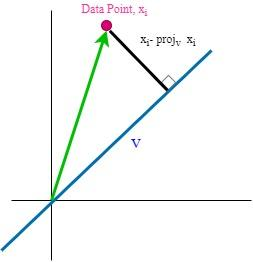

Figure 1.Figure shows the orthogonal distance, ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} -{\textrm{proj}}_{\mathit{\mathbf{v}}} \;{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}}$, between the line v and data point $x_i \ldotp$

We are given $n$ data points the columns of the matrix **X** contains the data points ranging from 1 to n. We need to find the direction of vector,  $\mathit{\mathbf{v}}$, which reduces the orthogonal distance, $x_{i\;} -{\textrm{proj}}_v \;x_i$, for n data points.  Since we are only interested in the direction of vector, we can safely assume ${\left\|\mathit{\mathbf{v}}\right\|}_2 =1$. This formulated mathematically as,

   
$$\underset{\mathit{\mathbf{v}}}{\textrm{minimize}\;} {\sum_{i=1}^n {\left\|{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} -{\textrm{proj}}_{\mathit{\mathbf{v}}} \;{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} \right\|}_{2\;} }$$



$$\textrm{subject}\;\textrm{to}:\;\;{\left\|\mathit{\mathbf{v}}\right\|}_2 =1$$


The above equation can be formulated to form a equaivalent maximization problem shown below, *(for detailed derivation consult Chapter 6 of  Numerical Algorithms by Justin Solomon)*

  
$$\underset{\mathit{\mathbf{v}}}{\mathrm{m}\textrm{axi}\textrm{mize}\;} {\mathit{\mathbf{v}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{X}}\;{\mathit{\mathbf{X}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{v}}$$



$$\textrm{subject}\;\textrm{to}:\;\;{\left\|\mathit{\mathbf{v}}\right\|}_2 =1$$


It can be shown that the eigen vector corresponding to the dominant eigen value, maximises the above equation. The vector $\mathit{\mathbf{v}}$ is known as the principal component of the dataset. It can be computed using the Power Iteration method.

Use your power iteration method written in Question 2 part (a) to compute the dominant eigen vector. You can also use the MATLAB's function eig()  to compute the eigen vector.

Use the above two approaches and plot the best straight line fit through the data on the same graph. Comment on the results, explain any differences/similarities in both approaches. What is the error being minimized in each case?

**Both methods find a line of best fit of the form y = ax passing through the origin for the given data. The two have different error metrics, where linear regression minimizes vertical distances, while PCA minimizes orthogonal distances. They also have different geometric interpretations, as regression treats x as an independent variable and y as a dependent variable, whereas PCA treats x and y symmetrically, finding inherent structure. Linear regression minimizes Minimizes Σ(y_i - ax_i)² and is better when your goal is to predict y values, whereas PCA minimizes Σ[(y_i - ax_i)²/(1+a²)] and is better for finding the true geometric pattern of the data. **

load('Data_PCA.mat')


% use x_plot to plot the lines obtained by PCA and regression
x_plot = linspace(-3,3,100); 


% % % % % % % WRITE YOUR CODE HERE % % % % % % %
%% Write code below to approximate the parameter a using the Leastsquares
%% method, and evaluage y_ls = a*x_plot;

%for a line y = ax passing through origin, this is formula for a using
%least squares method
a_reg = (x'*y)/(x'*x);
y_reg = a_reg * x_plot;

%% Wrtoe code below to approximate the parameter a using the PCA
%% method, and evaluage y_PCA = a*x_plot;
%create data matrix
X = [x y]';

%compute X*X' matrix
C = X'*X;
%find eigenvector corresponding to dominant eigenvalue
[V, D] = eig(C);
[~, idx] = max(diag(D));
v_pca = V(:, idx);


v_pca = v_pca / norm(v_pca);

%calc slope from eigenvector components 
a_pca = v_pca(2) / v_pca(1);
y_pca = a_pca * x_plot;



%calculate and print errors for comparison
%linear regression error (sum of squared vertical distances)
err_reg = sum((y - a_reg*x).^2);
fprintf('Linear Regression Error (vertical): %.6f\n', err_reg);

Linear Regression Error (vertical): 481.642975



%PCA error (sum of squared orthogonal distances)
err_pca = sum(((y - a_pca*x).^2) ./ (1 + a_pca^2));
fprintf('PCA Error (orthogonal): %.6f\n', err_pca);

PCA Error (orthogonal): 52.126434


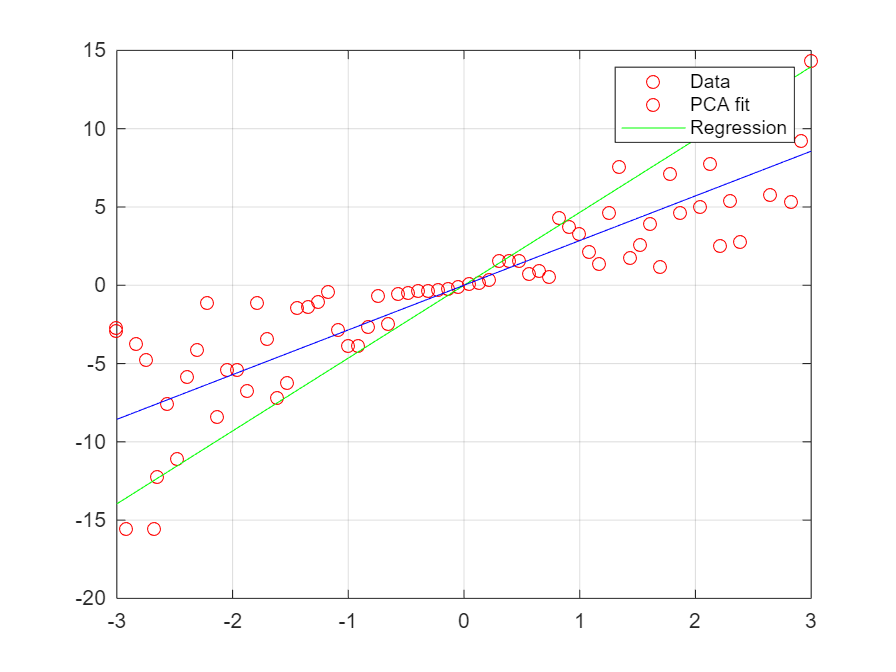


%%%%%%%%%%%%%%  PLOTS  %%%%%%%%%%%%%%%%%%%%%%%%%
figure(1)
hold on 
grid on 
plot(x,y,'ro') % plot given data 
plot(x_plot,y_pca, 'g-')
plot(x_plot,y_reg, 'b-')
legend('Data','PCA fit', 'Regression')

Question 4: **Nonlinear Equations for univariate case. (10 marks)**

a) Bisection Method is used for finding the roots of a continuous function, $f\left(x\right)$, given endpoints;$a,b$ with $f\left(a\right)\ldotp f\left(b\right)<0$ . The interval $\left\lbrack a\;\;b\right\rbrack$contains a root, $x_r$, because $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Bisection method bisects the given interval at the midpoint, $c=\frac{a+b}{2}$ and then chooses a new interval based such that end of point of interval have opposite signs, i.e., if $f\left(a\right)\ldotp f\left(c\right)<0$, then the new interval is set to $\left\lbrack a\;\;c\right\rbrack$, else if $f\left(c\right)\ldotp f\left(b\right)<0$ then the interval is set to $\left\lbrack c\;\;b\right\rbrack$.

The above procedure is repeated until the following two conditions are simultaneously met, 

- The function value at the interval is sufficiently small, i.e., ${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The new interval is sufficiently small, i.e., ${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

Implement the Bisection Method in the cell below to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ in the interval $\left\lbrack -3\;\;\;0\right\rbrack \;$using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$. **Show the number of iterations the bisection method took to converge.**

Use the cell below to implement your code. 

Implement the function in the appendix and use the cell below to run it.

%implement your bisection method here
f=@(x)x^4-2*x^2-4;
a = -3;
b = 0;
tol = 1e-5;
[c,counter]= bisectionMethod(f,a,b,tol)

c = -1.7989

counter = 20

b) ** Newton-Raphson**

 Bisection Method requires the given function,$f\left(x\right)$ to be continuous, Newton-Raphson requires $f\left(x\right)$ to be continuous and differentiable. While the Newton- Raphson method converges faster than the bisection method, however, Newton-Raphson method does not guarantee convergence. Newton-Raphson works by linearising the $f\left(x\right)$, at the given initial guess, $x^{\left(0\right)}$as shown below


$$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$$


Setting the expression on the right to zero, provides an approximation to the root, and we obtain


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


Then, the function,$\;f\left(x\right)$, is again linearised using approximation,$x^{\left(1\right)}$as the initial guess, to obtain new approximation of the root. After $k$ iterations the new approximation for the root becomes,

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|\Delta x^{\left(k+1\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

where $\Delta x^{\left(k+1\right)} =$$x^{\left(k+1\right)} -x^{\left(k\right)}$.

Implement the **Newton-Raphson** Method to find the root of $f\left(x\right)=x^4 -{2\;x}^2 -4$ use intial guess of $x^{\left(0\right)} =-3$ using $\epsilon_{\textrm{tolerance}} ={10}^{-5}$.  If the convergence is not reached in 100 iterations, quit the algorithm by displaying an error message indicating that Newton-Raphson failed to converge. 

Plot the 2-Norm of difference between consecutive solutions ${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$  for each iteration. 

% write your code here
f=@(x)x^4-2*x^2-4;
fderivative = @(x)4*x^3-4*x;  % write the value of derivative
x0 = -3;
tol = 1e-5;
nmax = 100;
 

[x,deltaX]=newtonraphson(f,fderivative,x0,tol,nmax)

x = -1.7989

deltaX =     0.6146    0.3798    0.1705    0.0348    0.0013    0.0000


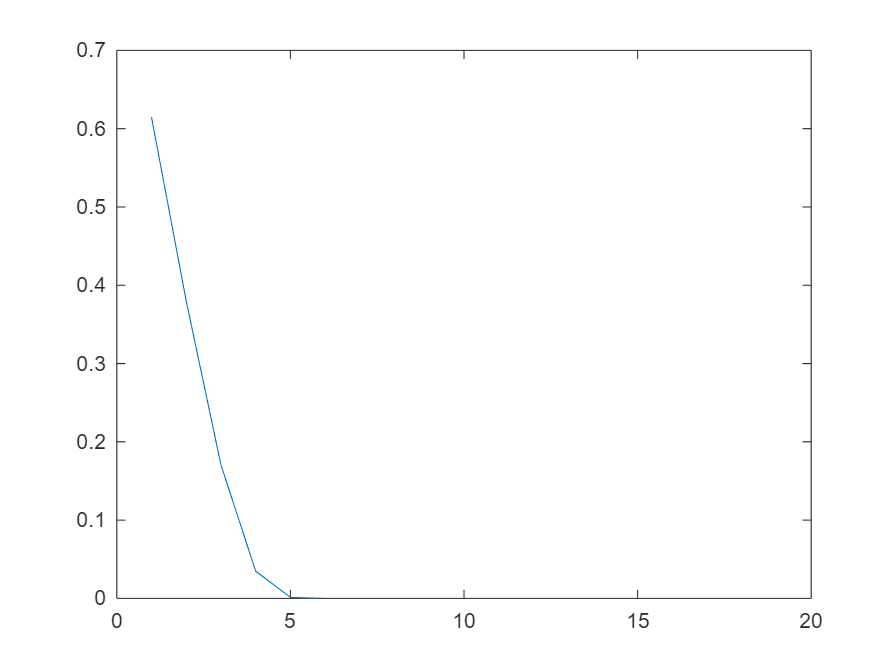

figure;
plot(deltaX)
xlim ([0,20]);

## Question 5: (20 marks)

**Nonlinear Equations for N-variables.**

 Newton-Raphson Method can be used to solve the system of nonlinear equations of N-variables, $\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$shown below,


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


The above equations can be written as a vector valued function as shown below,


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


where $\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$ is the vector containing all the variables.

Following the idea of unidimensional Newton-Rapshson, we start with an initial guess ${\mathit{\mathbf{X}}}^{\left(0\right)}$ and we use this to linearise the function $\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$ around${\;\mathit{\mathbf{X}}}^{\left(0\right)}$ 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


Setting the expresson on the left side to zero, we find the approximation of the solution vector. After $k$ iteration the approximation for the solution vector can be written as 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


where $\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$ is the vector valued fucntion evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$ and $\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$ is the jacobian evaluated at ${\mathit{\mathbf{X}}}^{\left(k\right)}$. The structure of the Jacobian is given by,


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


The above procedure is repeated untill the following two convergence condtions are simultaneously met,  

- The function value at new guess point is sufficiently small, i.e., ${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- The difference between the two consecutive solutions is sufficiently small, i.e., ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

Find a solution of the following system of three nonlinear equations using Newton-Raphson method.


$$x_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 \;=3$$



$$x_{1\;}^{2\;} +\;x_2^2 -x_{3\;} =1$$



$$x_{1\;} +x_{2\;} +x_3 =3$$


Note that this can be expressed as 

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
x_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 -3\\
x_{1\;}^{2\;} +\;x_2^2 -x_{3\;} -1\\
x_{1\;} +x_{2\;} +x_3 -3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$,        where $\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

a) Write a MATLAB function named *evaluateEquations(x)*, that evaluates the above equation at a given input vector. Use the provided $\mathit{\mathbf{X}}$ to manualy check your implementation.

% X in this case is an example
 
X = [2;3;4];

f  = evaluateEquations(X)

f =     26
     8
     6


b) Write a MATLAB function named *evaluateJacobian()*, that evaluates the Jacobian of the above equations. Use the provided $\mathit{\mathbf{X}}$ to manualy check your implementation.

X = [2;3;4];
J  = evaluateJacobian(X)

J =      4     6     8
     4     6    -1
     1     1     1


**Newton-Raphson **

c) Implement the Newton-Raphson method, use the function named *NewtonRaphson() *to write the code for this. 

Start with intial guess, $X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack }^T$  and then find a suitable intial guess. Plot the 2-Norm of difference between consecutive solutions ${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$ for each iteration. 

% write your code here
func =@evaluateEquations;
Jac =@evaluateJacobian;
%our initial guess
Xguess = [1.2; 1.6; 0.8]; %I made this initial guess asymmetrical to avoid the problem of singularity
[X,counter,deltaX] = NewtonRaphson(func,Jac,Xguess,1e-5)

X =     1.0000
    1.0000
    1.0000


counter = 18

deltaX =     0.8107    0.4054    0.2027    0.1014    0.0507    0.0253    0.0127    0.0063    0.0032    0.0016    0.0008    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000


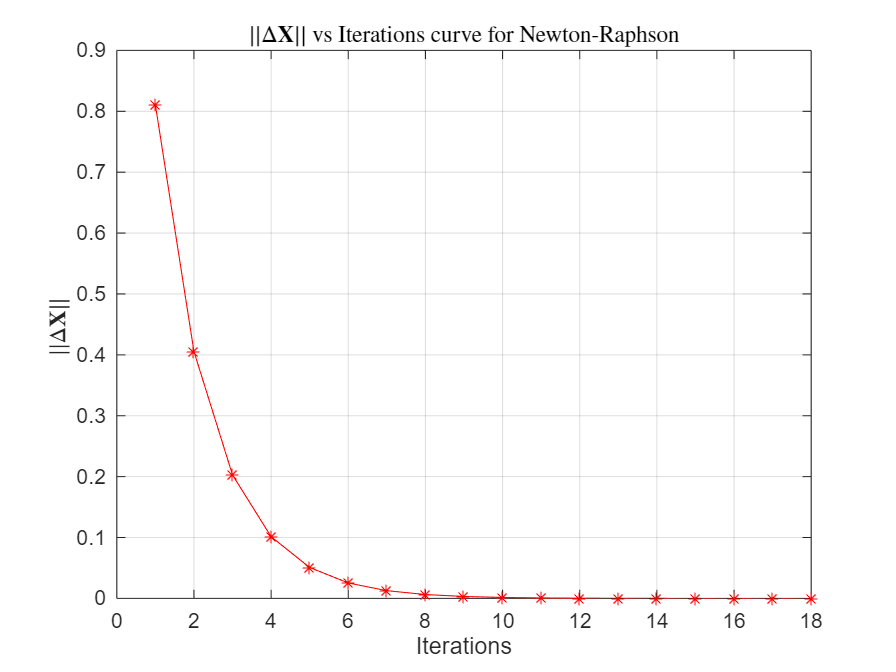



figure;
plot(deltaX,'r-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  vs Iterations curve for Newton-Raphson', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Jacobian**

d) Suppose you do not have access to the Jacobian of  the nonlinear eqautions, use the Broyden's method  to compute/ update the Jacobian.  

At the $(k+1)^{th}$ iteration of Newton Raphson, the soltuion vector $\mathit{\mathbf{X}}$  is given by 


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


let, $J_{k\;} =\;\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$. Using the Broyden's update, $J_{k\;}$ can be computed as 


$$J_{k\;} =J_{k-1} +\;\frac{\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;-\;\;J_{k-1} \;\;\left({\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \right)\;}{{\left\|\;\;\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\;\right)\;\;\right\|}_2^{2\;} }{\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\right)}^T$$


Write a MATLAB function named* NR_Broyden_Jacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for Jacobian $J_0  =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.


func =@evaluateEquations;
Xguess = [1.2; 1.6; 0.8];
[Xout,deltaXBroyden]  = NR_Broyden_Jacobian(func, Xguess,1e-5)

Xout =     1.0097
    0.9903
    1.0000


deltaXBroyden = 1.0e+03 *

    0.0028    0.0023    0.0024    0.0310    0.0330    0.0344    0.0303    0.0074    0.0367    0.0513    0.0911    0.1227    1.4057    1.4088    0.0034    0.0398    0.0101    0.0079    0.0042    0.0025    0.0013    0.0007    0.0004    0.0006    0.0029    0.0033    0.0013    0.0019    0.0005    0.0026    0.0032    0.0019    0.0025    0.0004    0.0012    0.0050    0.0054    0.0005    0.0015    0.0012    0.0020    0.0012    0.0018    0.0007    0.0017    0.0066    0.0068    0.0001    0.0003    0.0001


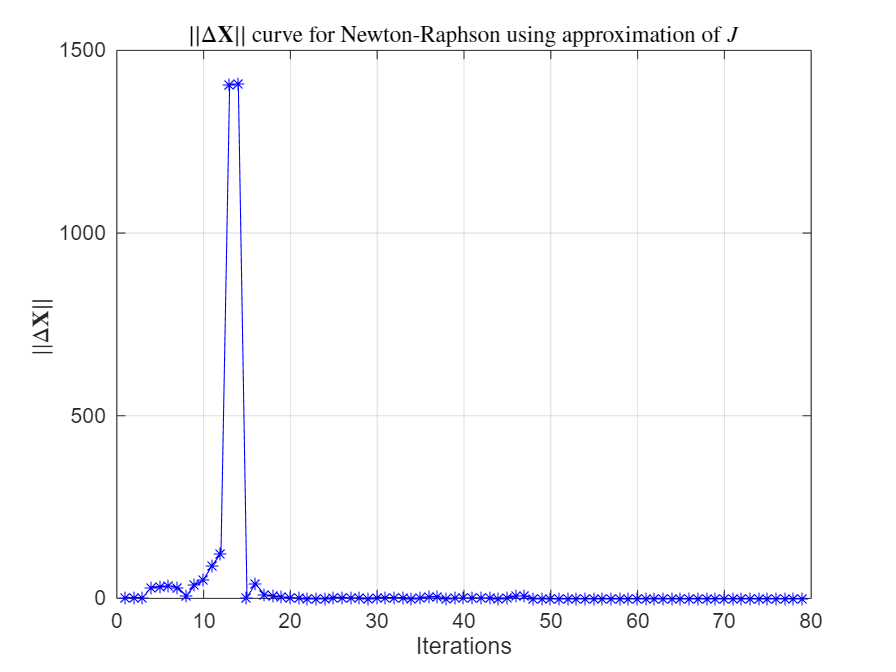

figure;
plot(deltaXBroyden,'b-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J$', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's method to approximate Inverse of Jacobian**

e)  In part d) , you implemented the Broyden's method for updating the Jacobian, in this part use the Broyden's update for computing inverse of Jacobian. The inverse of Jacobian can be computed as 


$$J_{k\;}^{-1} =J_{k-1}^{-1} +\;\frac{\;\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)-\;J_{k-1}^{-1\;} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;}{{\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} J_{k-1}^{-1} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)}\left({\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} \;J_{k-1}^{-1} \right)$$


Write a MATLAB function named* NR_Broyden_InvJacobian()*, that evaluates the Jacobian of the above equations. 

Use the initial guess,$X^{\left(0\right)}$ you used in part c). For the intial guess for inverse of Jacobian $J_0^{-1} =I_{n\times n}$, where $I_{n\times n}$ is the identity matrix and $n$ is the number of equations.

Use the framework of the function provided in the Appendix.

Xguess = [1.2; 1.6; 0.8];
func =@evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,1e-5)

Xout =     1.0029
    0.9971
    1.0000


deltaXBroyden = 1.0e+03 *

    0.0028    0.0023    0.0024    0.0310    0.0330    0.0344    0.0303    0.0074    0.0367    0.0513    0.0911    0.1227    1.4057    1.4087    0.0034    0.0398    0.0101    0.0079    0.0042    0.0025    0.0013    0.0007    0.0004    0.0006    0.0029    0.0033    0.0013    0.0019    0.0005    0.0026    0.0032    0.0019    0.0025    0.0004    0.0012    0.0050    0.0054    0.0005    0.0015    0.0013    0.0020    0.0011    0.0018    0.0009    0.0016    0.0015    0.0020    0.0004    0.0331    0.0331


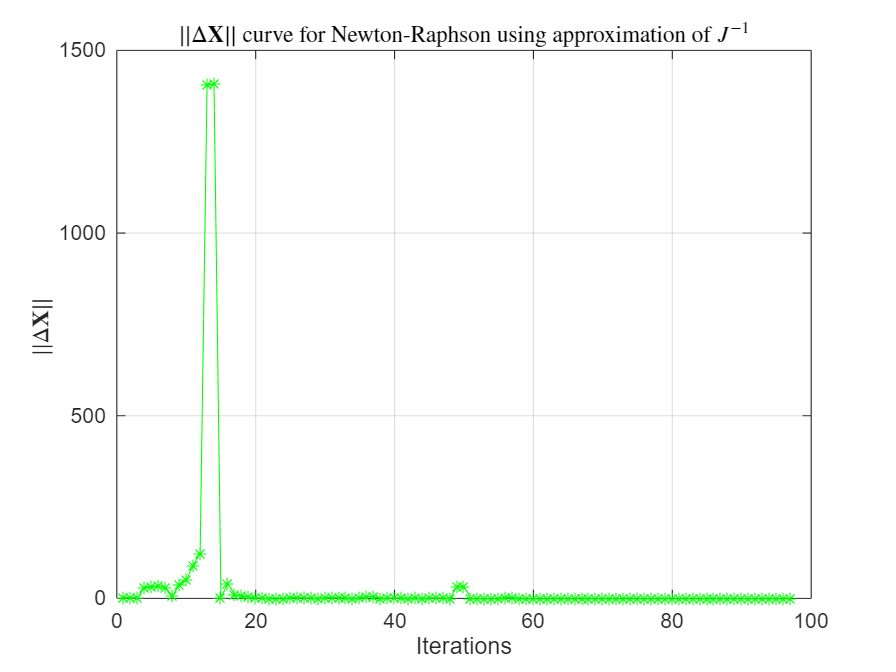

figure;
plot(deltaXBroyden,'g-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J^{-1}$', 'Interpreter', 'latex')

f)  Given a nonlinear system with $n$ number of nonlinear equations, shown below,


$$f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;=3x_{1\;} -2x_{1\;}^2 -2x_{2\;} +1=0$$



$$f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;\;=3x_{i\;} -2{x_i }_{\;}^2 -x_{i-1} -2x_{i+1} +1=0,\;\;\;\;\;\textrm{for}\;\;\;1<i<n$$


 
$$f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)=3x_{n\;} -2{x_n }_{\;}^2 -x_{n-1} +1=0$$


where, $x_1$, $x_2$, ..., $x_n$  are the variables. 

The nonlinear vector of equations can written as, 


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
f_2 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


The Matlab function to evalaute the above function is named *nlfunction() *and  it is  provided to you in appendix. 

Suppose you  do not have access to the jacobian, so you chose to solve the above nonlinear function using Broyden's methods you developed in part (d) and (e). The code cell below uses the Broyden's algorithms you implemented in paer d) and  e) to solve the above nonlinear system for different size of the system ranging from  $10\le n\le 200$. 

Run the cell below and explain the results

clear all
func1 = @nlfunction;
c = 1

c = 1

N = 200

N = 200

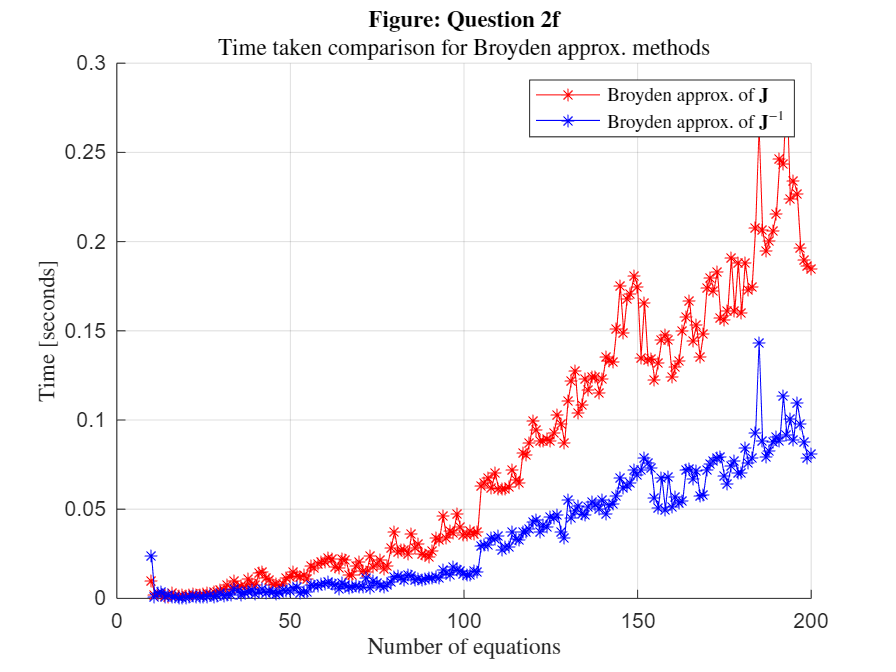

time_BroydenIJ = zeros(N-10+1,1);
time_BroydenJ = zeros(N-10+1,1);
for I=10:N
Xguess = zeros(I,1);
brIJstart =tic ;
[XBrIJ,deltaXBroyden]  = NR_Broyden_InvJacobian(func1,Xguess,1e-6);
time_BroydenIJ(c) = toc(brIJstart) ;

brJstart =tic ;
[XBrJ,deltaXBroyden]  = NR_Broyden_Jacobian(func1,Xguess,1e-6);
time_BroydenJ(c) = toc(brJstart) ;

c =c +1;
end

figure()
clf
hold on 
plot(10:N,time_BroydenJ,'r-*')
plot(10:N,time_BroydenIJ,'b-*')

legend('Broyden approx. of $\textbf{J}$' ,'Broyden approx. of $\textbf{J}^{-1}$','Interpreter','latex')
title({'\textbf{Figure: Question 2f}','Time taken comparison for Broyden approx. methods'}, 'Interpreter', 'latex')
ylabel('Time [seconds]', 'Interpreter', 'latex')
xlabel('Number of equations', 'Interpreter', 'latex')
grid on 

% Write your explanation here 

**The graph clearly demonstrates that the Broyden inverse Jacobian method (blue line) consistently outperforms the standard Broyden Jacobian method (red line) across all system sizes, with the performance gap widening as the number of equations increases. This efficiency difference occurs because the standard method approximates the  Jacobian matrix and then must solve a linear system (J·dx = -F) at each iteration—an O(n³) operation that becomes increasingly expensive with larger systems. In contrast, the inverse Jacobian method directly maintains and updates an approximation of J⁻¹, allowing it to compute the step direction through simple matrix-vector multiplication (dx = -J⁻¹·F)—an O(n²) operation. This approach cleverly avoids explicitly inverting any matrices; rather, it builds the inverse approximation iteratively through rank-one updates. The timing results confirm that for large nonlinear systems, the inverse Jacobian variant provides substantial computational savings, requiring roughly one-third the processing time of the standard method for systems with 200 equations while achieving comparable accuracy.**

# Appendix

Write the code for the function here.

function [F] = nlfunction(x)
% x is a colmns vecotr.
% Evaluate the vector function

n = length(x);
F = zeros(n,1);
i = 2:(n-1);
F(i) = (3-2*x(i)).*x(i)-x(i-1)-2*x(i+1) + 1;
F(n) = (3-2*x(n)).*x(n)-x(n-1) + 1;
F(1) = (3-2*x(1)).*x(1)-2*x(2) + 1;
end

Question 2 (a):  

function [eigen_value,vector]= power_method(A,tol)
% Write you code here

    [n, m] = size(A);
    %initialize a random vector, a random vector almost certainly contains
    %components of all eigenvectors of the matrix
    vector = rand(n, 1);
    vector = vector / norm(vector);

    %initialize difference to be greater than tolerance so our loop
    %initially runs 
    difference = tol + 1;
    %try to prevent an infinite loop
    max_iterations = 1000;
    iteration = 0;


    while difference >= tol && iteration < max_iterations
        old_v = vector;
        w = A * vector;
        vector = w / norm(w);
        difference = norm(vector - old_v);
        iteration = iteration + 1;
    end
    % Compute the eigenvalue using the Rayleigh quotient
    eigen_value = vector' * A * vector;

end

Question 2 (b):

function [V,eigenValues] = simultaneous_orthogonalisation(A,tol)
% eigen is the vector containing Eigen Values
% V is the vector containing Eigen Vectors. 
% Each column of V contains the eigen vectors for a given eigen value.
% Write you code here
    [n,m] = size(A);
    Q = eye(n);

    %initialize difference to be greater than tolerance so our loop
    %initially runs 
    difference = tol + 1;
    %try to prevent an infinite loop
    max_iterations = 1000;
    iteration = 0;

    while difference >= tol && iteration < max_iterations
        old_Q = Q;
        %each column gets "pushed" towards the eigenspace
        AQ = A * Q;
        %QR decomp
        [Q, R] = qr(AQ, 0);
        difference = norm(Q-old_Q);
        iteration = iteration + 1;
    end

    %after finding eigenvectors, we calculate eigenvalues 
    eigenvectors = Q;
   
    eigenvalues = zeros(n, 1);
    for i = 1:n
        eigenvalues(i) = eigenvectors(:,i)' * A * eigenvectors(:,i);
    end
    %sort eigenvalues by magnitude with the largest first
    [~, idx] = sort(abs(eigenvalues), 'descend');
    eigenValues = eigenvalues(idx);
    V = eigenvectors(:, idx);

end

Question 2 (c):

function [V,eigenValues] = QR_algorithm(A,tol)
% eigen is the vector containing Eigen Values
% V is the vector containing Eigen Vectors. 
% Each column of V contains the eigen vectors for a given eigen value.
% Write you code here
    [n,m] = size(A);
    A_current = A;
    max_iterations = 1000;
    iteration = 0;
    converged = false;
    %initialize eigenvectors
    V = eye(n);
    
    while ~converged && iteration < max_iterations
        [Q,R] = qr(A_current);
        %use these Q matrices to get eigenvectors
        V = V*Q;
        
        %use the A[k+1] = R[k]*Q[K] formula given in question
        A_next = R*Q;
        
        %check for convergence 
        lower_triangular = tril(A_next, -1);
        if norm(lower_triangular, 'fro') < tol
            converged = true;
        end
        
        %update our k for our next iteration 
        A_current = A_next;
        iteration = iteration + 1;
    end


    %sort for consistency and readibility
    eigenValues = diag(A_current);
    [~, idx] = sort(abs(eigenValues), 'descend');
    eigenValues = eigenValues(idx);
    V = V(:, idx);

    


end

QUESTION 4a)

function [c, counter] = bisectionMethod(f, a, b, tol)
    counter = 0;
    
    while true
        counter = counter + 1;
        
        c = (a + b) / 2;
        
        if abs(f(c)) < tol || abs(b - a) < tol
            break;
        end
        
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
    end
end

QUESTION 4b)

function [x, deltaX] = newtonraphson(f, df, x0, tol, nmax)

    x = x0;
    deltaX = [];
    

    for i = 1:nmax
        %calculate next approximation
        x_new = x - f(x)/df(x);
        
        %calculate difference for plotting
        diff = abs(x_new - x);
        deltaX(i) = diff;
        
        %update x
        x = x_new;
        
        %check both convergence conditions
        if abs(f(x)) < tol && diff < tol
            break;
        end
    end
    
    %check if we hit maximum iterations without converging
    if i == nmax && (abs(f(x)) >= tol || diff >= tol)
        error('Newton-Raphson failed to converge in %d iterations', nmax);
    end
end

Question 5a)

function f = evaluateEquations(x)

    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    
    f = zeros(3, 1);
    f(1) = x1^2 + x2^2 + x3^2 - 3;    
    f(2) = x1^2 + x2^2 - x3 - 1;       
    f(3) = x1 + x2 + x3 - 3;
end

Question 5b)


function J = evaluateJacobian(x)
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    

    J = zeros(3, 3);
    
    %partial derivatives for first equation: x1^2+x2^2+x3^2-3 = 0
    J(1,1) = 2*x1;
    J(1,2) = 2*x2;
    J(1,3) = 2*x3;
    
    %partial derivatives for second equation: x1^2+x2^2-x3-1 = 0
    J(2,1) = 2*x1;
    J(2,2) = 2*x2;
    J(2,3) = -1;
    
    %partial derivatives for third equation: x1+x2+x3-3 = 0
    J(3,1) = 1;       
    J(3,2) = 1;       
    J(3,3) = 1;       
end

Question 5c) 

function [X, counter, deltaX] = NewtonRaphson(func, Jac, Xguess, tol)
    X = Xguess;
    counter = 0;
    deltaX = [];
    max_iterations = 500;
    while counter < max_iterations
        counter = counter + 1;
        F = func(X);
        J = Jac(X);
        %solve linear system J*dx = -F for update
        dx = -J\F;
        
        %update solution
        X_new = X + dx;
        
        %calculate 2-norm of difference between consecutive iterations
        diff = norm(X_new - X, 2);
        deltaX(counter) = diff;
        %update X for next iteration
        X = X_new;
        
        %check both convergence conditions
        if norm(func(X), 2) < tol && diff < tol
            break;
        end
    end
    if counter == max_iterations && (norm(func(X), 2) >= tol || diff >= tol)
        warning('Newton-Raphson failed to converge in %d iterations', max_iterations);
    end
end

Question 5d) 

function [Xout, deltaXBroyden] = NR_Broyden_Jacobian(func, Xguess, tol)
    X_current = Xguess;

    J_current = eye(length(Xguess));

    max_iterations = 500;

    deltaXBroyden = [];

    %Evaluate the function at our initial point 
    F_current = func(X_current);
    
    for n = 1:max_iterations
        %the +1e-10 is added to avoid singularity problems, as matrix can become
        %ill conditioned throughout the course of the iterations
        dx = -(J_current + 1e-10*eye(length(X_current)))\F_current;
        X_next = X_current + dx;

        %calculate norm of difference for convergence check 
        diff = norm(X_next - X_current, 2);
        deltaXBroyden(n) = diff;

        %evaluate function at new point 
        F_next = func(X_next);

        %check for convergence
        if norm(F_next, 2) < tol || diff < tol
            break;
        end

        %broyden update!
        deltaF = F_next - F_current;
        deltaX = X_next - X_current;
        numerator = deltaF - J_current*deltaX;
        denominator = deltaX'*deltaX;
        J_next = J_current + (numerator * deltaX') / denominator;

        %update for next run through loop
        X_current = X_next;
        F_current = F_next;
        J_current = J_next;
    end
    if n == max_iterations && (norm(func(X_current), 2) >= tol || diff >= tol)
        warning('Newton-Raphson with Broyden update failed to converge in %d iterations', max_iterations);
    end
    Xout = X_current;

end

Question 5e)

function [Xout, deltaXBroyden] = NR_Broyden_InvJacobian(func, Xguess, tol)
 X_current = Xguess;
 invJ_current = eye(length(Xguess));
 max_iterations = 500;
 deltaXBroyden = [];
 
 %Evaluate the function at our initial point
 F_current = func(X_current);
 
 for n = 1:max_iterations
    %Directly compute update using inverse Jacobian approximation
    dx = -invJ_current * F_current;
    
    X_next = X_current + dx;
    
    %calculate norm of difference for convergence check
    diff = norm(X_next - X_current, 2);
    deltaXBroyden(n) = diff;
    
    %evaluate function at new point
    F_next = func(X_next);
    
    %check for convergence
    if norm(F_next, 2) < tol || diff < tol
        break;
    end
    
    %broyden inverse jacobian update!
    deltaX = X_next - X_current;
    deltaF = F_next - F_current;
    
    %calculate terms for the inverse Jacobian update formula
    term1 = deltaX - invJ_current * deltaF;
    term2 = deltaX' * invJ_current;
    denominator = deltaX' * invJ_current * deltaF;
    
    %add small value to avoid division by near-zero
    if abs(denominator) < 1e-10
        denominator = denominator + 1e-10;
    end
    
    %update inverse Jacobian approximation
    invJ_next = invJ_current + (term1 * term2) / denominator;
    
    %update for next run through loop
    X_current = X_next;
    F_current = F_next;
    invJ_current = invJ_next;
 end
 
 if n == max_iterations && (norm(func(X_current), 2) >= tol || diff >= tol)
    warning('Newton-Raphson with Broyden inverse Jacobian update failed to converge in %d iterations', max_iterations);
 end
 
 Xout = X_current;
end

You can use the space below to write any additional funcitons if needed.